# Project 0 - Tutorial

## (1) Download Files.

[http://www.stat.ucla.edu/~sczhu/Courses/UCLA/Stat_231/Stat_231.html](http://www.stat.ucla.edu/~sczhu/Courses/UCLA/Stat_231/Stat_231.html)

files: (1) description, (2) cifar data, (3) matlab code

## (2) References.

(1) configure mex (matlab c compiler support, **might cause trouble on linux**)

[https://www.mathworks.com/help/matlab/matlab_external/changing-default-compiler.html](https://www.mathworks.com/help/matlab/matlab_external/changing-default-compiler.html)

(2) compile matconvnet (network library)

[http://www.vlfeat.org/matconvnet/install/](http://www.vlfeat.org/matconvnet/install/)

(3) cifar-10 (data)

[https://www.cs.toronto.edu/~kriz/cifar.html](https://www.cs.toronto.edu/~kriz/cifar.html)

(4) paperspace (cheap GPU)

[https://www.paperspace.com/ml](https://www.paperspace.com/ml)

## (3) Project Description.

root = pwd()

root = 'E:\work\pattern\project0\src'

cd(root);
open('Project_0_description.pdf');

Error using open (line 85)
File 'Project_0_description.pdf' not found.

(1) conv net structure: (1) convolution, (2) pooling, (3) relu, (4) soft-max.

(2) block structure: (1) output / input must match.

(3) disuss tasks.

## (4) Look at cifar-10 data.

60,000 32x32 rgb color images in 10 classes.

50,000 training images and 10,000 test images.

stored in matlab *.mat format.

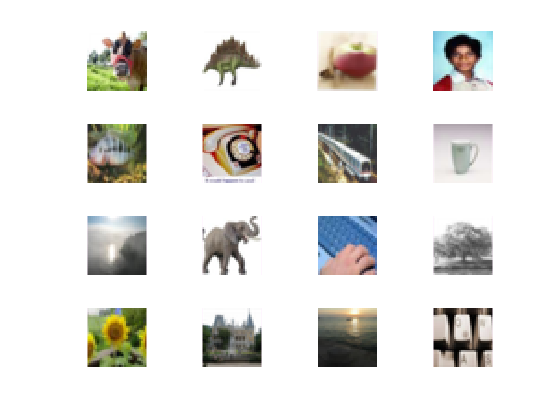

cd(root);
cd('cifar-100-matlab');
load('train.mat');
figure;
for i = 1:(4^2)
    subplot(4,4,i);
    imshow(permute(reshape(data(i,:), [32, 32, 3]), [2 1 3 4]),[]);
end

## (5) Look at code.

cd(root);
cd('code/examples/');

setup.m                   -> compiles matconvnet

cnn_cifar.m             -> entry point: (1) downloads cifar, (2) reads cifar, (3) train model, (4) save model

cnn_cifar_init.m       -> block structure of network **(modify this)**

process_epoch.m    -> compute gradients, backprop (do not touch)

## (6) Task 1: Train full LeNet, plot training/testing error.

Train LeNet. Trains 30 epochs, takes about **3 hours. May use GPU (**[paperspace.com](https://www.paperspace.com/ml)**).**

cd(root);
cd('code/examples/');

mex -setup

MEX configured to use 'Microsoft Visual C++ 2015 Professional (C)' for C language compilation.
	 variables with more than 2^32-1 elements. You will be required
	 to update your code to utilize the new API.
	 You can find more information about this at:
	 <a href="http://www.mathworks.com/help/matlab/matlab_external/upgrading-mex-files-to-use-64-bit-api.html">http://www.mathworks.com/help/matlab/matlab_external/upgrading-mex-files-to-use-64-bit-api.html</a>.

To choose a different language, select one from the following:
 mex -setup C++ 
 mex -setup FORTRAN


mex -setup C++

MEX configured to use 'Microsoft Visual C++ 2015 Professional' for C++ language compilation.
	 variables with more than 2^32-1 elements. You will be required
	 to update your code to utilize the new API.
	 You can find more information about this at:
	 <a href="http://www.mathworks.com/help/matlab/matlab_external/upgrading-mex-files-to-use-64-bit-api.html">http://www.mathworks.com/help/matlab/matlab_external/upgrading-mex-files-to-use-64-bit-api.html</a>.



run('setup.m')

Building with 'Xcode Clang++'.
MEX completed successfully.
Building with 'Xcode Clang++'.
MEX completed successfully.
Building with 'Xcode Clang++'.
MEX completed successfully.
Building with 'Xcode Clang++'.
MEX completed successfully.
Building with 'Xcode Clang++'.
MEX completed successfully.
Building with 'Xcode Clang++'.
MEX completed successfully.
Building with 'Xcode Clang++'.
MEX completed successfully.
Building with 'Xcode Clang++'.
MEX completed successfully.
Building with 'Xcode Clang++'.
MEX completed successfully.
Building with 'Xcode Clang++'.
MEX completed successfully.
Building with 'Xcode Clang++'.
MEX completed successfully.
Building with 'Xcode Clang++'.
MEX completed successfully.
Building with 'Xcode Clang++'.
MEX completed successfully.
Building with 'Xcode Clang++'.
MEX completed successfully.
Building with 'Xcode Clang++'.
MEX completed successfully.
Building with 'Xcode Clang++'.
MEX completed successfully.
Building with 'Xcode Clang++'.
MEX completed successfull


%vl_testnn();
disp('Compilation Finished');
run('cnn_cifar.m');

Extract training / validation error.

cd(root);
cd('code/examples/data/cifar-lenet/');

res = load('net-epoch-30.mat');
disp(res.info.train.error);

  Columns 1 through 16

    0.6115    0.4646    0.4086    0.3706    0.3480    0.3253    0.3055    0.2986    0.2821    0.2808    0.2665    0.2559    0.2501    0.2427    0.2406    0.1912

  Columns 17 through 30

    0.1838    0.1781    0.1762    0.1728    0.1726    0.1698    0.1680    0.1681    0.1678    0.1618    0.1582    0.1593    0.1583    0.1589



disp(res.info.val.error);

  Columns 1 through 16

    0.5024    0.4412    0.4024    0.3532    0.3363    0.3125    0.3176    0.3220    0.2927    0.2918    0.2820    0.2939    0.2783    0.2774    0.2663    0.2358

  Columns 17 through 30

    0.2313    0.2297    0.2260    0.2276    0.2233    0.2288    0.2208    0.2265    0.2247    0.2201    0.2208    0.2212    0.2202    0.2206





epochNum = linspace(1, 30, 30);
set(0, 'defaultfigurecolor',[1 1 1])
figure(1);
hold on
plot(epochNum, res.info.train.error, 'LineWidth',3);
plot(epochNum, res.info.val.error, 'LineWidth',3);
title('Training and Validation Error (full)');
legend('Train Error', 'Validation Error');
xlabel('Epoch');
ylabel('Error');
%axis([1 30 0.1 0.7]);
hold off

## (6) Task 2: Remove blocks.

Adjust block structure of network:

cd(root);
cd('code/examples/');

open('cnn_cifar_init.m');

Remember to **change filter size** of block 5. **Remove block 5 and softmax layer.** Then

cd(root);
cd('code/examples/');

net = cnn_cifar_init();

net.layers = net.layers(1:end-1); % remove softmax
net.layers = net.layers(1:end-1); % remove block5

img = rand([32,32,3], 'single');
res = vl_simplenn(net, img);
res(end)

ans = struct with fields:
               x: [4×4×64 single]
            dzdx: []
            dzdw: []
             aux: []
            time: 0
    backwardTime: 0


**Careful**: Results from previous task will be **overwritten**. Rename mat files or change code (e.g. add suffix).

cd(root);
cd('code/examples/');

copyfile model.mat model-full.mat;
copyfile data/cifar-lenet/net-epoch-30.mat data/cifar-lenet/net-epoch-30-full.mat;

## **(7) Task 3: Visualize filter response.**

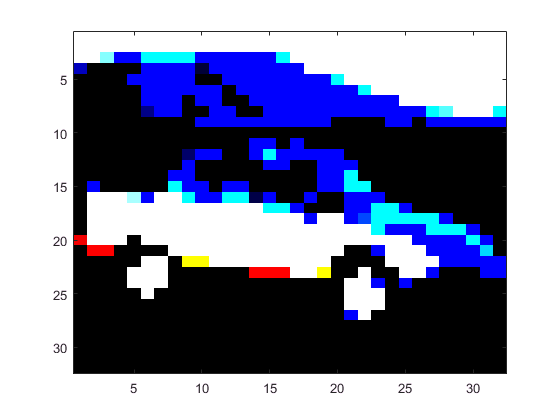

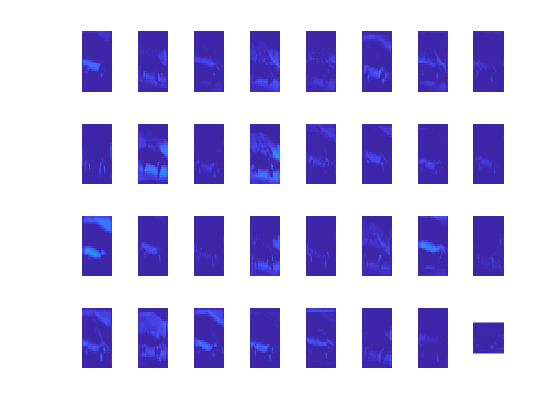

cd(root);
run(fullfile(root, 'code', 'matlab', 'vl_setupnn.m'));

cd(root);
cd('code/examples/');
model = load('model.mat');
model.net.layers = model.net.layers(1:end-1); % remove softmax

draw_filter_response(model, net);

## **(8) Sample report.**

cd(root);
open('sample_report.pdf');